% forward boost
num20=[2617333941027815725631725840014120507157828232792978227200  577738469790551866457722473405871467613465224508693335244800  2717016303976038398282643901267351276967574554532903079764664320  400331880559986717380573585100336510653161865775982093594644480  14504660225267551455712727265763972137285756095051448975360000];
  den20=[1526498274249280345880847760407830301683187764428800  707732422318605195195326985140519712159654894737817600  1493871501658587805312267467462970824883356687488721616896  359646340608871726916900274739789664188070195959150870201034  54832204560018210639248424461308795862014408004198967924885  2064711063683524897430756278539456187979940094126168473600];
  G20= tf(num20,den20); %plant_tf
  pz_G20=zpk(G20);
  G_monic = tf(num20/den20(1), den20/den20(1))

G_monic =
 
    1.715e06 s^4 + 3.785e08 s^3 + 1.78e12 s^2 + 2.623e11 s + 9.502e09
  ---------------------------------------------------------------------
  s^5 + 463.6 s^4 + 9.786e05 s^3 + 2.356e08 s^2 + 3.592e07 s + 1.353e06
 
Continuous-time transfer function.



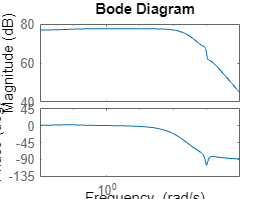

  bode(G20);

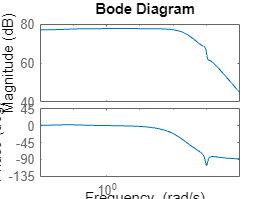

Kp =0.14031*0.0013;
Ki =0.14031;
 C = tf([Kp Ki], [1 0]);
ol20=minreal(((G20))*C);
 cl20 = feedback(ol20, 1);
%  bode(cl20)
%  [GM, PM, Wgc, Wpc] = margin(cl20);
%  margin(cl20)
% bw = bandwidth(cl20);

num40=[1822786137501514523207809067152691067484916090695109836800  390975225941414332241456527898553642076558997848453231411200  1891655124432247862078624889323907675442220976917097099613102080  242844940049292419034122592427930269586185008453200282097971200  7794023589894270886194805557646533776897345671091611238400000];
den40=[1063097012423605955167018975998310388672220050227200  486248924904178171155487899483228152381410151655014400  1038440576189005112546837691834107655505618551686639386624  248516038085042509876201394380504647600310668746322829546366  33096289792254385422853360865580465682222839834506001460815  1100682110197927435127987798121923778973691370813784064000];
G40= tf(num40,den40); %plant_tf
pz_G40=zpk(G40);
bode(G40);

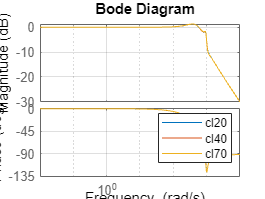

Kp =0.14031*0.0013;
Ki =0.14031;
C = tf([Kp Ki], [1 0]);
ol40=minreal(((G40))*C);
cl40 = feedback(ol40, 1);



num70=[6730287276928669008767295017179167018405844027181944012800 1401785947124357668248182230824556371011026948275170181120000  6982570253718778723771714296113800317628677089117728836602388480  922427102281413650291524070999161185726373717886205938153533440  30441430150572395443102111481274275682776750429317449646080000];
den70=[3925281276641006603693608526762992204328197108531200  1770993099363051642206473294356888590539519040264601600  3827150575039332094557524733116712346502389056437280047104  910485609981689931799636509677311244661031141182784847394790  124753242473478468733203606092101893144456185654301812425539  4270586429049907845501678035997936945678598900053494988800];
G70= tf(num70,den70); %plant_tf
pz_G70=zpk(G70);

Kp =0.14031*0.0013;
Ki =0.14031;
C = tf([Kp Ki], [1 0]);
ol70=minreal(((G70))*C);
cl70 = feedback(ol70, 1);


bode(cl20, cl40, cl70)
grid on
legend('cl20','cl40', 'cl70')
 grid on